function [X_Est, P_Est, GT] = myEKF(out)

    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;
    GT_time = out.GT_time.time;

    Sensor_GYRO_val = squeeze(out.Sensor_GYRO.signals.values);
    Sensor_GYRO_time = out.Sensor_GYRO.time;
    Sensor_ToF1_val = squeeze(out.Sensor_ToF1.signals.values);
    Sensor_ToF1_time = out.Sensor_ToF1.time;
    Sensor_ToF2_val = squeeze(out.Sensor_ToF2.signals.values);
    Sensor_ToF2_time = out.Sensor_ToF2.time;
    Sensor_ToF3_val = squeeze(out.Sensor_ToF3.signals.values);
    Sensor_ToF3_time = out.Sensor_ToF3.time;

    if size(Sensor_GYRO_val,1) == 3 && size(Sensor_GYRO_val,2) > 3
        Sensor_GYRO_val = Sensor_GYRO_val';
    end
     if size(Sensor_ToF1_val,1) == 4 && size(Sensor_ToF1_val,2) > 4
        Sensor_ToF1_val = Sensor_ToF1_val';
    end
      if size(Sensor_ToF2_val,1) == 4 && size(Sensor_ToF2_val,2) > 4
        Sensor_ToF2_val = Sensor_ToF2_val';
    end
      if size(Sensor_ToF3_val,1) == 4 && size(Sensor_ToF3_val,2) > 4
        Sensor_ToF3_val = Sensor_ToF3_val';
    end


    eul = quat2eul(GT_rotation);
    yaw_ground_truth = eul(:,1);
    GT = [GT_position(:,1), GT_position(:,2), yaw_ground_truth];

    num_steps = length(GT_time);
    state_dim = 4; % x, y, yaw, bias_z
    X_Est = zeros(num_steps, state_dim);
    P_Est = zeros(state_dim, state_dim, num_steps);

    % --- Initialize State ---
    X_hat = zeros(state_dim, 1);
    X_hat(1) = GT(1,1); % x
    X_hat(2) = GT(1,2); % y
    X_hat(3) = GT(1,3); % yaw
    X_hat(4) = 0;       % b_z (initial guess)

    % --- Initialize Covariance ---
    P = diag([ (0.01)^2, ...     % Initial uncertainty in x (m^2)
                (0.01)^2, ...     % Initial uncertainty in y (m^2)
                (0.1*pi/180)^2, ... % Initial uncertainty in yaw (rad^2)
                (0.5*pi/180)^2 ]); % *** INCREASED Initial uncertainty in gyro bias (rad/s)^2 ***

    X_Est(1,:) = X_hat';
    P_Est(:,:,1) = P;

    % --- Tuning Parameters ---
    v_const = 0.18; % Robot forward speed assumption (m/s) - NEEDS TUNING

    % Process Noise Covariance Q (reflects uncertainty in process model)
    q_pos = (0.08)^2;      % Uncertainty in position prediction (related to velocity model)
    q_yaw = (0.1*pi/180)^2; % Uncertainty in yaw prediction (gyro noise after bias)
    q_bias = (0.05*pi/180)^2; % *** INCREASED Uncertainty in bias stability (how fast bias drifts) ***
    Q = diag([q_pos, q_pos, q_yaw, q_bias]);

    % Measurement Noise Covariance R (reflects ToF sensor accuracy)
    R_tof = (0.07)^2;      % ToF measurement variance (m^2) - TUNE THIS

    % Outlier Rejection Threshold (Mahalanobis Distance Squared)
    mahalanobis_threshold = 5.0; % TUNE THIS

    % Arena and Sensor Configuration
    X_max = 1.0;
    Y_max = 1.0;
    arena_dims = [0, X_max; 0, Y_max];
    tof1_offset = [0.1, 0];
    tof2_offset = [0, 0.08];
    tof3_offset = [0, -0.08];

    last_tof1_time = -1;
    last_tof2_time = -1;
    last_tof3_time = -1;

    for k = 2:num_steps
        dt = GT_time(k) - GT_time(k-1);
        if dt <= 0 % Handle potential duplicate timestamps or non-increasing time
             if k > 2
                 dt_alt = GT_time(k) - GT_time(k-2);
                  if dt_alt > 0
                     dt = dt_alt / 2;
                 else
                     dt = 1/200; % Default guess if time is stuck
                 end
             else
                 dt = 1/200;
             end
             if dt <= 0
                dt = 1/200;
             end
        end

        current_time = GT_time(k);

        % --- Prediction Step ---
        gyro_idx = find(Sensor_GYRO_time <= current_time, 1, 'last');
        if isempty(gyro_idx)
            gyro_idx = 1;
        end

        gyro_z_meas = Sensor_GYRO_val(gyro_idx, 3);

        x_prev = X_hat(1);
        y_prev = X_hat(2);
        yaw_prev = X_hat(3);
        bz_prev = X_hat(4);

        omega_corrected = gyro_z_meas - bz_prev;

        x_pred = x_prev + v_const * cos(yaw_prev) * dt;
        y_pred = y_prev + v_const * sin(yaw_prev) * dt;
        yaw_pred = yaw_prev + omega_corrected * dt;
        yaw_pred = wrapToPi(yaw_pred);
        bz_pred = bz_prev;

        X_pred = [x_pred; y_pred; yaw_pred; bz_pred];

        F = eye(state_dim);
        F(1, 3) = -v_const * sin(yaw_prev) * dt;
        F(2, 3) =  v_const * cos(yaw_prev) * dt;
        F(3, 4) = -dt;

        P_pred = F * P * F' + Q;
        P_pred = (P_pred + P_pred') / 2;


        % --- Measurement Update Step (Correction) ---
        z_indices = [];
        z_meas = [];
        z_pred_vec = [];
        H_list = [];

        tof_sensors = {Sensor_ToF1_val, Sensor_ToF1_time, tof1_offset, 0,    last_tof1_time;
                       Sensor_ToF2_val, Sensor_ToF2_time, tof2_offset, pi/2, last_tof2_time;
                       Sensor_ToF3_val, Sensor_ToF3_time, tof3_offset, -pi/2,last_tof3_time};

        new_last_times = [last_tof1_time, last_tof2_time, last_tof3_time];

        for sensor_idx = 1:size(tof_sensors, 1)
            sensor_val = tof_sensors{sensor_idx, 1};
            sensor_time = tof_sensors{sensor_idx, 2};
            sensor_offset = tof_sensors{sensor_idx, 3};
            sensor_angle = tof_sensors{sensor_idx, 4};
            last_time = tof_sensors{sensor_idx, 5};

            tof_idx = find(sensor_time <= current_time & sensor_time > last_time, 1, 'last');

            if ~isempty(tof_idx)
                 new_last_times(sensor_idx) = sensor_time(tof_idx);

                 meas_tof = sensor_val(tof_idx, 1);
                 status_tof = sensor_val(tof_idx, 4);

                 if (status_tof == 2 || status_tof == 4) && meas_tof < 1.5 && meas_tof > 0.02

                     [z_p, H_i_xyz] = predict_measurement_and_jacobian_xyz(X_pred(1:3), sensor_offset, sensor_angle, arena_dims);

                     if ~isnan(z_p) && ~any(isnan(H_i_xyz))
                         H_i_full = [H_i_xyz, 0];
                         innovation = meas_tof - z_p;
                         S_i = H_i_full * P_pred * H_i_full' + R_tof;

                         if S_i > 1e-9 % Avoid division by zero or near-zero
                             mahalanobis_sq = innovation * inv(S_i) * innovation;
                             if mahalanobis_sq < mahalanobis_threshold
                                 z_indices(end+1) = sensor_idx;
                                 z_meas = [z_meas; meas_tof];
                                 z_pred_vec = [z_pred_vec; z_p];
                                 H_list = [H_list; H_i_full];
                             end
                         end
                     end
                 end
            end
        end

        last_tof1_time = new_last_times(1);
        last_tof2_time = new_last_times(2);
        last_tof3_time = new_last_times(3);

        if ~isempty(z_meas)
            H = H_list;
            R = diag(repmat(R_tof, length(z_meas), 1));
            y = z_meas - z_pred_vec;
            S = H * P_pred * H' + R;

            try
                S_chol = chol(S); % Use Cholesky factorization for inversion - more stable
                S_inv = inv(S_chol') * inv(S_chol);
                % S_inv = inv(S); % Original less stable method
                K = P_pred * H' * S_inv;

                X_hat = X_pred + K * y;
                X_hat(3) = wrapToPi(X_hat(3));

                I = eye(state_dim);
                P = (I - K * H) * P_pred;
                P = (P + P') / 2;

            catch ME
                 warning('Matrix inversion or Cholesky failed for S at k=%d. Skipping update. Msg: %s', k, ME.message);
                 X_hat = X_pred;
                 P = P_pred;
            end

        else
            X_hat = X_pred;
            P = P_pred;
        end

        X_Est(k,:) = X_hat';
        P_Est(:,:,k) = P;
    end

end


function [z_pred, H_xyz] = predict_measurement_and_jacobian_xyz(x_state_xyz, sensor_offset_body, sensor_angle_body, arena_dims)

    x = x_state_xyz(1);
    y = x_state_xyz(2);
    yaw = x_state_xyz(3);

    R_mat = [cos(yaw) -sin(yaw); sin(yaw) cos(yaw)];
    sensor_offset_global = R_mat * sensor_offset_body';

    sensor_pos = [x; y] + sensor_offset_global;
    sensor_angle_global = wrapToPi(yaw + sensor_angle_body);

    [z_pred, ~] = ray_cast(sensor_pos, sensor_angle_global, arena_dims);

    if isnan(z_pred) || isinf(z_pred)
        H_xyz = nan(1,3);
        z_pred = nan;
        return;
    end

    delta = 1e-7;
    H_xyz = zeros(1, 3);
    perturbations = [delta, 0, 0; 0, delta, 0; 0, 0, delta];

    for i = 1:3
        x_state_perturbed = x_state_xyz + perturbations(i, :)';
        x_p = x_state_perturbed(1);
        y_p = x_state_perturbed(2);
        yaw_p = wrapToPi(x_state_perturbed(3));

        R_mat_p = [cos(yaw_p) -sin(yaw_p); sin(yaw_p) cos(yaw_p)];
        sensor_offset_global_p = R_mat_p * sensor_offset_body';
        sensor_pos_p = [x_p; y_p] + sensor_offset_global_p;
        sensor_angle_global_p = wrapToPi(yaw_p + sensor_angle_body);

        [z_p, ~] = ray_cast(sensor_pos_p, sensor_angle_global_p, arena_dims);

        if isnan(z_p) || isinf(z_p)
             H_xyz = nan(1, 3);
             z_pred = nan;
             return;
        else
             H_xyz(i) = (z_p - z_pred) / delta;
        end
    end
end


function [distance, hit_point] = ray_cast(origin, angle, arena_dims)
    ox = origin(1);
    oy = origin(2);
    c = cos(angle);
    s = sin(angle);
    x_min = arena_dims(1,1);
    x_max = arena_dims(1,2);
    y_min = arena_dims(2,1);
    y_max = arena_dims(2,2);
    distances = [];
    points = [];
    tiny = 1e-9;
    if abs(c) > tiny
        t_xmax = (x_max - ox) / c;
        if t_xmax >= -tiny
            y_hit = oy + t_xmax * s;
            if y_hit >= y_min - tiny && y_hit <= y_max + tiny
                distances = [distances, max(0, t_xmax)];
                points = [points; x_max, y_hit];
            end
        end
        t_xmin = (x_min - ox) / c;
         if t_xmin >= -tiny
            y_hit = oy + t_xmin * s;
            if y_hit >= y_min - tiny && y_hit <= y_max + tiny
                distances = [distances, max(0, t_xmin)];
                points = [points; x_min, y_hit];
            end
         end
    end
    if abs(s) > tiny
        t_ymax = (y_max - oy) / s;
        if t_ymax >= -tiny
            x_hit = ox + t_ymax * c;
            if x_hit >= x_min - tiny && x_hit <= x_max + tiny
                 distances = [distances, max(0, t_ymax)];
                 points = [points; x_hit, y_max];
            end
        end
        t_ymin = (y_min - oy) / s;
        if t_ymin >= -tiny
            x_hit = ox + t_ymin * c;
             if x_hit >= x_min - tiny && x_hit <= x_max + tiny
                 distances = [distances, max(0, t_ymin)];
                 points = [points; x_hit, y_min];
             end
        end
    end
    if isempty(distances)
        distance = nan;
        hit_point = [nan, nan];
    else
        valid_indices = find(distances >= 0);
        if isempty(valid_indices)
            distance = nan;
            hit_point = [nan, nan];
        else
           [min_dist, min_idx_in_valid] = min(distances(valid_indices));
           original_idx = valid_indices(min_idx_in_valid);
           if min_dist < 1e-6
               min_dist = 1e-6;
           end
           distance = min_dist;
           hit_point = points(original_idx, :);
        end
    end
end

Run

data = load('trainingData/task2_1.mat');
out = data.out;

[X_Est, P_Est, GT] = myEKF(out)

X_Est =    -0.0118   -0.9589   -1.6828         0
   -0.0119   -0.9598   -1.6828         0
   -0.0120   -0.9607   -1.6828         0
   -0.0121   -0.9616   -1.6828         0
   -0.0122   -0.9625   -1.6828         0
   -0.0123   -0.9634   -1.6828         0
   -0.0124   -0.9643   -1.6828         0
   -0.0125   -0.9652   -1.6828         0
   -0.0126   -0.9661   -1.6828         0
   -0.0127   -0.9670   -1.6828         0


P_Est = P_Est(:,:,1) =

   1.0e-04 *

    1.0000         0         0         0
         0    1.0000         0         0
         0         0    0.0305         0
         0         0         0    0.7615


P_Est(:,:,2) =

    0.0065   -0.0000    0.0000         0
   -0.0000    0.0065   -0.0000         0
    0.0000   -0.0000    0.0000   -0.0000
         0         0   -0.0000    0.0001


P_Est(:,:,3) =

    0.0129   -0.0000    0.0000   -0.0000
   -0.0000    0.0129   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0001


P_Est(:,:,4) =

    0.0193   -0.0000    0.0000   -0.0000
   -0.0000    0.0193   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0001


P_Est(:,:,5) =

    0.0257   -0.0000    0.0000   -0.0000
   -0.0000    0.0257   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0001


P_Est(:,:,6) =

    0.0321   -0.0000    0.0000   -0.0000
   -0.0000 

GT =    -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6828
   -0.0118   -0.9589   -1.6829


Eval

% ------------------ Extract Data ------------------ %
pos_GT   = out.GT_position.signals.values;
rot_GT_quat_wxyz = out.GT_rotation.signals.values;
timeVec  = out.GT_time.time;

% Ensure timeVec is a column vector
if isrow(timeVec)
    timeVec = timeVec';
end

fprintf('Extracted GT Position, Rotation, and Time.\n');

Extracted GT Position, Rotation, and Time.



% ------------------ Ensure Consistent Lengths ------------------ %
N_gt_pos = size(pos_GT, 1);
N_gt_rot = size(rot_GT_quat_wxyz, 1);
N_time = length(timeVec);
N_est = size(X_Est, 1);

N = min([N_gt_pos, N_gt_rot, N_time, N_est]);

if N < max([N_gt_pos, N_gt_rot, N_time, N_est])
    fprintf('--- Warning: Truncating data lengths from max(%d, %d, %d, %d) to shortest N = %d ---\n', ...
            N_gt_pos, N_gt_rot, N_time, N_est, N);
    pos_GT = pos_GT(1:N, :);
    rot_GT_quat_wxyz = rot_GT_quat_wxyz(1:N, :);
    timeVec = timeVec(1:N);
    X_Est = X_Est(1:N, :);
else
    fprintf('--- Data lengths consistent: N = %d ---\n', N);
end

--- Data lengths consistent: N = 10356 ---



if N == 0
    error('Effective data length is zero after checking consistency.');
end

% ------------------ Convert Ground Truth to rigidtform3d ------------------ %
fprintf('Converting Ground Truth to rigidtform3d array (N=%d)...\n', N);

Converting Ground Truth to rigidtform3d array (N=10356)...


gtTforms(N) = rigidtform3d;
yaw_GT = zeros(N, 1);
for i = 1:N
    qGT = quaternion(rot_GT_quat_wxyz(i,1), rot_GT_quat_wxyz(i,2), rot_GT_quat_wxyz(i,3), rot_GT_quat_wxyz(i,4));
    qGT = normalize(qGT);
    try
        RGT = rotmat(qGT, 'frame');
        tGT = pos_GT(i,:);
        gtTforms(i) = rigidtform3d(RGT, tGT);

        eulGT = eulerd(qGT, 'ZYX', 'frame');
        yaw_GT(i) = deg2rad(eulGT(1));
    catch ME_gt_conv
        warning('Error converting GT pose at index %d: %s. Skipping step.', i, ME_gt_conv.message);
         gtTforms(i) = rigidtform3d(); % Assign default empty object
         yaw_GT(i) = NaN;
         % Consider breaking or setting a flag if too many errors occur
    end
end
yaw_GT = wrapToPi(yaw_GT);
fprintf('Ground Truth conversion complete.\n');

Ground Truth conversion complete.



% ------------------ Convert Estimated States to rigidtform3d ------------------ %
fprintf('Converting Estimated States to rigidtform3d array (N=%d)...\n', N);

Converting Estimated States to rigidtform3d array (N=10356)...


estTforms(N) = rigidtform3d;
yaw_Est = wrapToPi(X_Est(:, 3)); % Ensure estimated yaw is also wrapped

for i = 1:N
    tEst = [X_Est(i, 1), X_Est(i, 2), 0];
    yaw_est_i = yaw_Est(i);

    REst = [cos(yaw_est_i), -sin(yaw_est_i), 0;
            sin(yaw_est_i),  cos(yaw_est_i), 0;
            0,             0,            1];

    estTforms(i) = rigidtform3d(REst, tEst);
end
fprintf('Estimated States conversion complete.\n');

Estimated States conversion complete.



% ------------------ Compare Trajectories ------------------ %
fprintf('Attempting trajectory comparison using compareTrajectories...\n');

Attempting trajectory comparison using compareTrajectories...



--- Trajectory Comparison Results ---


Absolute RMSE not calculated or unavailable.


Relative RMSE not calculated or unavailable.


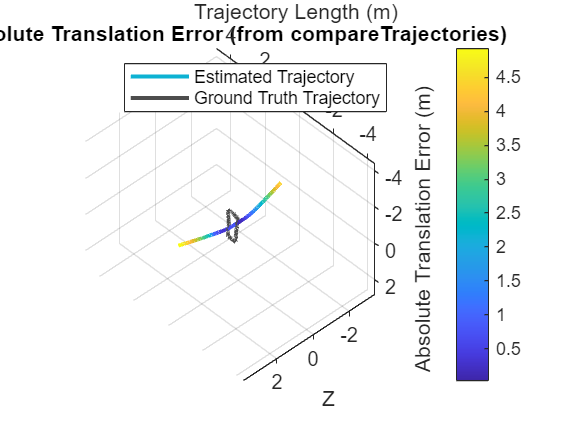

compareTrajectories executed successfully.


metrics = [];
canCompare = false;

% --- Check MATLAB version ---
try
    v = ver('MATLAB');
    versionYear = str2double(regexp(v.Release, 'R(\d{4})[ab]', 'tokens', 'once'));
    if ~isempty(versionYear) && (versionYear > 2024 || (versionYear == 2024 && contains(v.Release, 'R2024b')))
        canCompare = true;
    end
catch
     warning('Could not determine MATLAB version reliably.');
end

if ~canCompare
     warning('compareTrajectories requires MATLAB R2024b or newer. Skipping comparison.');
else
    try
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');

        fprintf('\n--- Trajectory Comparison Results ---\n');
        if isfield(metrics, 'AbsoluteRMSE') && numel(metrics.AbsoluteRMSE) >= 2
            fprintf('Absolute RMSE (m):                       %.4f\n', metrics.AbsoluteRMSE(2));
        else
             fprintf('Absolute RMSE not calculated or unavailable.\n');
        end
         if isfield(metrics, 'RelativeRMSE') && numel(metrics.RelativeRMSE) >= 2
            fprintf('Relative RMSE (drift error):             %.4f\n', metrics.RelativeRMSE(2)); % Check docs for unit, often m/m or rad/m
        else
             fprintf('Relative RMSE not calculated or unavailable.\n');
        end
         if isfield(metrics, 'RMSE') % Overall combined RMSE
             fprintf('Overall RMSE (combined translation+rotation): %.4f\n', metrics.RMSE);
         end

        % Plotting results from compareTrajectories
        try
            figure('Name', 'Trajectory Comparison: Absolute Translation Error');
            plot(metrics, "absolute-translation");
            title('Absolute Translation Error (from compareTrajectories)');
            xlabel('Trajectory Length (m)');
            ylabel('Absolute Translation Error (m)');
            grid on;
        catch plotME
             warning('Failed to plot metrics using plot(metrics,...): %s', plotME.message);
        end
        fprintf('compareTrajectories executed successfully.\n');

    catch ME_compare
        warning('Failed to execute compareTrajectories: %s', ME_compare.message);
        fprintf('Ensure MATLAB R2024b or newer and necessary toolboxes (e.g., Aerospace) are installed.\n');
    end
end


% ------------------ Plot Position Comparison ------------------ %
fprintf('Plotting Position Estimate vs Ground Truth...\n');

Plotting Position Estimate vs Ground Truth...


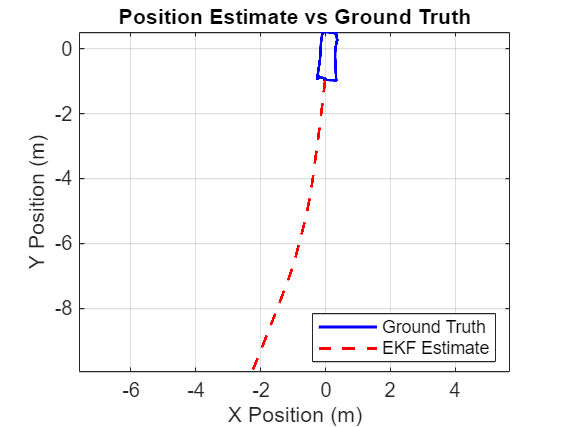

figure('Name', 'Position Estimate vs Ground Truth');
plot(pos_GT(:,1), pos_GT(:,2), 'b-', 'LineWidth', 1.5, 'DisplayName', 'Ground Truth');
hold on;
plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate');
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Position Estimate vs Ground Truth');
legend('show', 'Location', 'best');
axis equal;
grid on;
hold off;


% ------------------ Plot Yaw Comparison (using unwrap) ------------------ %
fprintf('Plotting Yaw Estimate vs Ground Truth...\n');

Plotting Yaw Estimate vs Ground Truth...


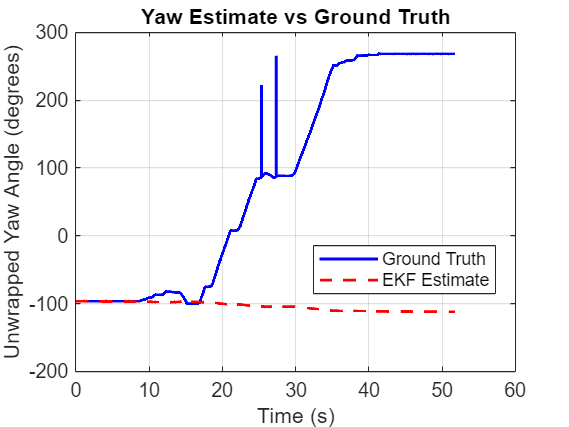

figure('Name', 'Yaw Estimate vs Ground Truth');
plot(timeVec, rad2deg(unwrap(yaw_GT)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'Ground Truth');
hold on;
plot(timeVec, rad2deg(unwrap(yaw_Est)), 'r--', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate');
xlabel('Time (s)');
ylabel('Unwrapped Yaw Angle (degrees)');
title('Yaw Estimate vs Ground Truth');
legend('show', 'Location', 'best');
grid on;
hold off;


% ------------------ Plot Yaw Error ------------------ %
fprintf('Plotting Yaw Estimation Error...\n');

Plotting Yaw Estimation Error...


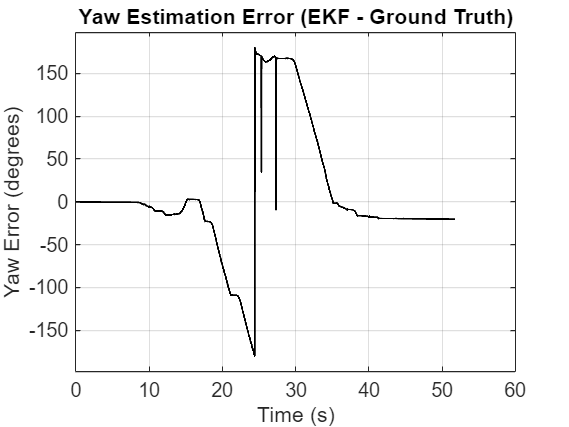

yaw_error = wrapToPi(yaw_Est - yaw_GT);
figure('Name', 'Yaw Estimation Error');
plot(timeVec, rad2deg(yaw_error), 'k-', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Yaw Error (degrees)');
title('Yaw Estimation Error (EKF - Ground Truth)');
grid on;
max_err = max(abs(rad2deg(yaw_error)));
if ~isnan(max_err) && max_err > 0
    ylim([-max_err*1.1, max_err*1.1]);
end


fprintf('--- End of Evaluation Script ---\n');

--- End of Evaluation Script ---
